# prepare the data

triancount=3000

triancount = 3000

testcount=100

testcount = 100

% the data is 10 mins interval we may reduce it to 1 hour
interval=6

interval = 6

% the model lag
lag=20;
% left last 100 for testing
trainsample=exp8((end-interval*(triancount+testcount))+1:interval:(end-interval*testcount),2:5)

trainsample = 3000×4 table
    LVActivePowerkW    WindSpeedms    Theoretical_Power_CurveKWh    WindDirection
    _______________    ___________    __________________________    _____________

        834.95           7.1006                 1061.9                 53.956    
        834.88           7.0698                 1047.7                 52.147    
        1076.7           7.6845                 1354.8                 51.111    
        829.23           6.9923                 1012.5                 68.891    
        1073.9           7.5536                 1285.7                 68.554    
        960.77           7.2502                 1132.7                 68.274    
        1198.9           7.8084                 1422.3                 67.179    
        309.59           5.1155                 364.89                  70.62    
        530.43           5.7678                 549.43                 32.049    
        605.99           6.0979                 657.51                

testsample=exp8((end-interval*testcount)+1:interval:end,2:5)

testsample = 100×4 table
    LVActivePowerkW    WindSpeedms    Theoretical_Power_CurveKWh    WindDirection
    _______________    ___________    __________________________    _____________

           0             2.5852                      0                 2.1013    
           0             2.2794                      0                 355.21    
           0             2.2351                      0                 11.549    
           0               2.44                      0                 16.636    
           0             3.8042                 93.469                 33.699    
           0             3.2896                 31.977                 56.222    
           0             3.2024                 25.752                 60.316    
           0             3.2536                 29.258                 66.884    
           0             3.4022                 41.812                 64.525    
           0             3.4229                 43.843                 6

% check is there any nan in the data if so fill it
find(isnan(trainsample{:,:}))


ans =

  空的 0×1 double 列向量



% the model
model=varm(4,lag)

model =   varm - 属性:

     Description: "4-Dimensional VAR(20) Model"
     SeriesNames: "Y1"  "Y2"  "Y3"  ... and 1 more
       NumSeries: 4
               P: 20
        Constant: [4×1 vector of NaNs]
              AR: {4×4 matrices of NaNs} at lags [1 2 3 ... and 17 more]
           Trend: [4×1 vector of zeros]
            Beta: [4×0 matrix]
      Covariance: [4×4 matrix of NaNs]

% fit the model
EstMdl = estimate(model,trainsample{:,:})

EstMdl =   varm - 属性:

     Description: "AR-Stationary 4-Dimensional VAR(20) Model"
     SeriesNames: "Y1"  "Y2"  "Y3"  ... and 1 more
       NumSeries: 4
               P: 20
        Constant: [11.4657 0.473033 -4.54277 ... and 1 more]'
              AR: {4×4 matrices} at lags [1 2 3 ... and 17 more]
           Trend: [4×1 vector of zeros]
            Beta: [4×0 matrix]
      Covariance: [4×4 matrix]

## forcast

% forcast int 10 step into the future
steplen=10

steplen = 10

% initial tha matrxi, so you can rerun the section of code
pred=zeros(1,4)

pred =      0     0     0     0



% use previous lag sample to predict next steplen sample
for step=1:steplen:testcount-steplen+1
A    step
    pred = [pred;forecast(EstMdl,steplen,exp8{end-testcount+step-lag:end-testcount+step-1,2:5})];    
end

step = 1

step = 11

step = 21

step = 31

step = 41

step = 51

step = 61

step = 71

step = 81

step = 91

pred

pred = 	1.0e+03 *

         0         0         0         0
    0.0030    0.0010    0.0128    0.2151
    0.1308    0.0015    0.1234    0.1917
    0.0874    0.0016    0.0545    0.1855
    0.2101    0.0023    0.1741    0.1809
    0.3570    0.0028    0.3332    0.1882
    0.5409    0.0035    0.5038    0.1789
    0.5103    0.0036    0.4795    0.1752
    0.5811    0.0039    0.5489    0.1772
    0.7129    0.0044    0.7037    0.1863


## plot

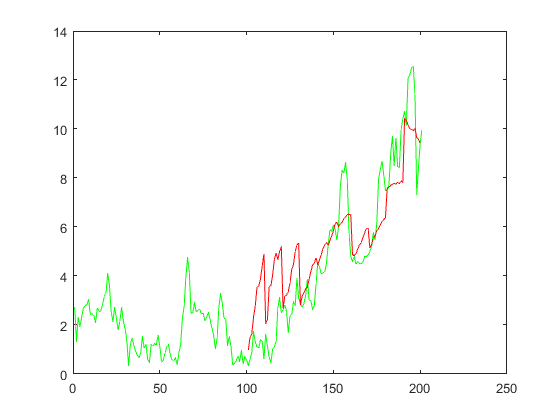


plot(exp8.WindSpeedms(end-200:end),"g")
hold on
plot(linspace(101,200,100),pred(2:end,2),"r")
hold off